# 1. Repàs de la segmentació per watershed

orig = imread("cornea.tif");

Error using imread>get_full_filename (line 566)
File "cornea.tif" does not exist.

Error in imread (line 375)
    fullname = get_full_filename(filename);

figure,imshow(orig);

ee = strel('disk',1);
% calculem el gradient. Ho podem fer morfològic
grad=imsubtract(imdilate(orig,ee),imerode(orig,ee));
figure,imshow(grad),title('gradient')
% mirem de segmentar les cèlules fent watershed sobre la imatge gradient
segm=watershed(grad);
im2 =imcomplement(segm);
rm=imregionalmax(im2);

figure,imshow(rm), title('segmentacio per watershed')
% resultat sobresegmentat. Cal treballar amb markers

## marker-controlled watershed

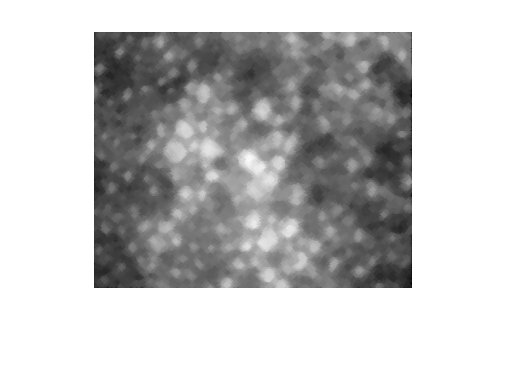

% usarem els màxims regionals com a markers de les cèlules
% la imatge és molt sorollosa. Cal filtrar abans
ee=strel('disk',2);
filt=imopen(imclose(orig,ee),ee); %filtre OC
figure,imshow(filt)

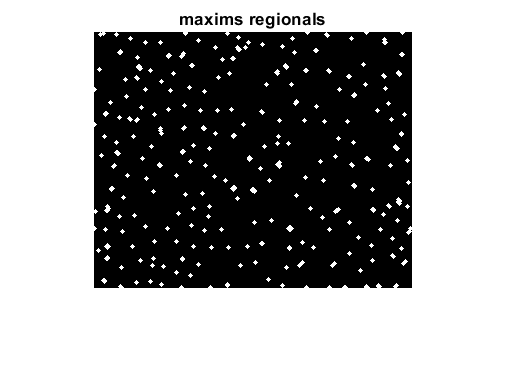

rm=imregionalmax(filt);
figure,imshow(rm),title('maxims regionals')

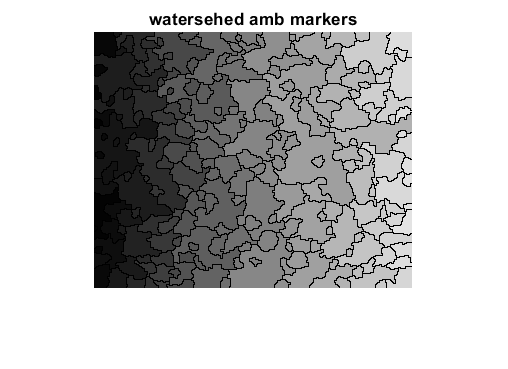

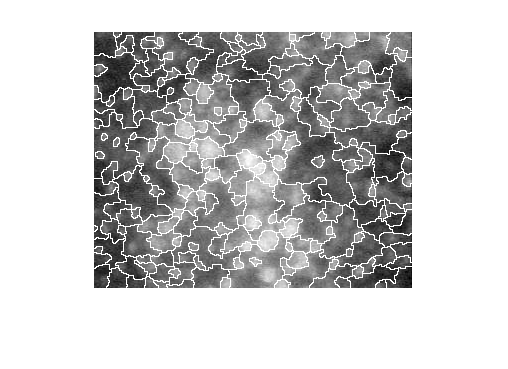

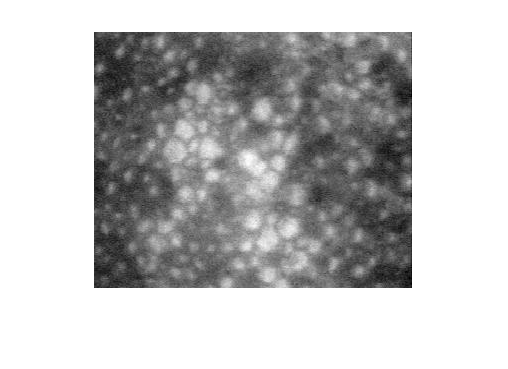

% Usem els maxims regionals com a markers pel watershed
segm=watershed(imimposemin(grad,rm));
figure,imshow(segm),title('watersehed amb markers')

%Feu un overlay, en color, dels contorns obtinguts sobre la imatge original
%Us sembla correcta la segmentació? O ens em oblidat alguna cosa ?
p = imcomplement(segm);
l = uint8(imregionalmax(p));
k = l*255 + orig;
imshow(k);
imshow(orig);
%Hi ha sobresegmentació, degut a que no hem aplicat watershed amb un marker
%al fons


## Cal trobar un marker pel fons

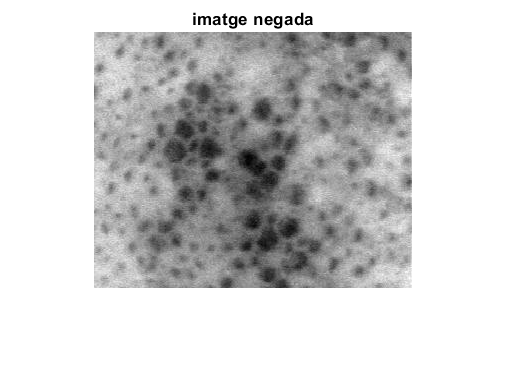

% L'obtenim fent el watershed de la imatge negada.
%Usem com a markers els mateixos maxims d'abans
Norig=imcomplement(orig);
figure,imshow(Norig),title('imatge negada')

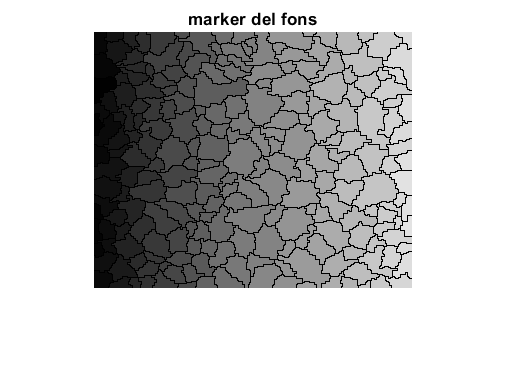

fons=watershed(imimposemin(Norig,rm));
figure,imshow(fons),title('marker del fons')

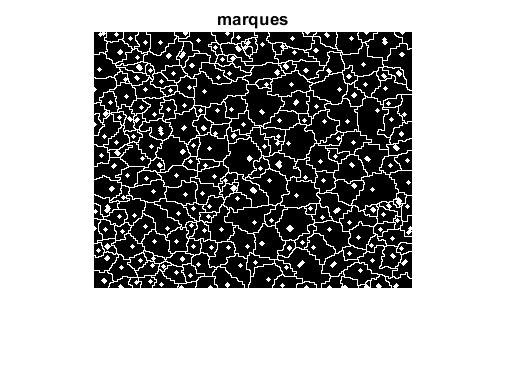

% Fem una imatge de markers a partir de les celules i del fons
markers=~fons|rm;
figure,imshow(markers),title('marques')

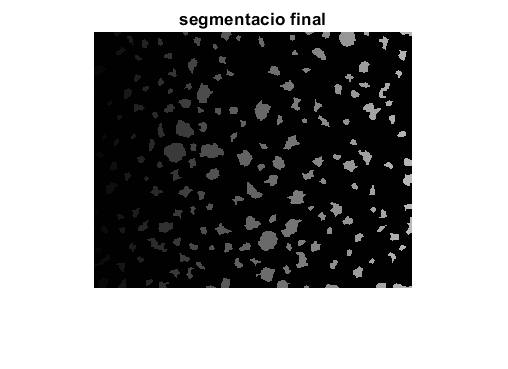

% fem el watershed amb les noves marques
segm=watershed(imimposemin(grad,markers));
figure,imshow(segm),title('segmentacio final')

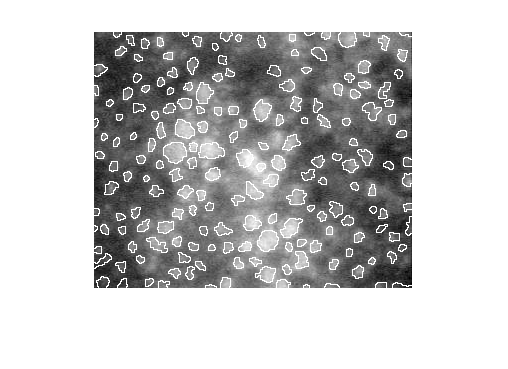


%Dibuixeu de nou el resultat en overlay
p = imcomplement(segm);
l = uint8(imregionalmax(p));
k = l*255 + orig;
imshow(k);

imshow(orig);

## hem perdut alguna cèlula.

% Aixó és degut a que alguns markers de les celules es toquen amb el marker del fons (veure
%imatge %markers’)
%Utilitzeu operacions morfològiques sobre les imatges de marques per a evitar que els markers es
%toquin. Genereu una nova imatge de marques.
%Segmenteu la imatge amb watershed usant les noves marques i mostreu el resultat en overlay




## 2. Segmentació per clustering. K-means

(completeu allò que es demana, i el que creieu que falta)

im = imread('peppers.png');
[MAXFILA MAXCOL chan]=size(im)

MAXFILA = 512

MAXCOL = 512

chan = 3

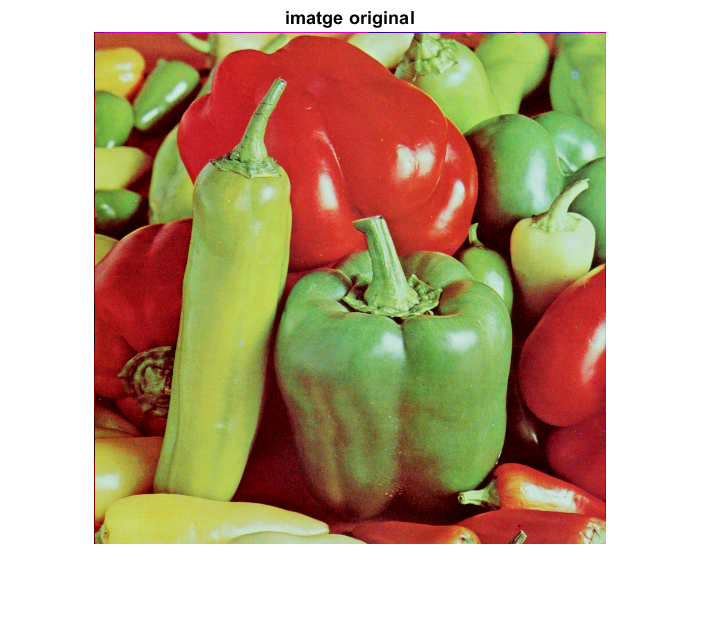

figure,imshow(im),title('imatge original')

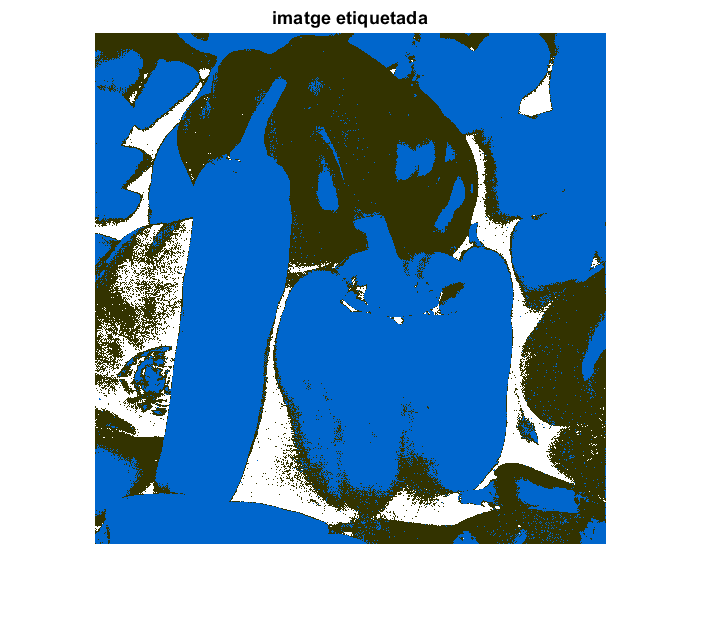

% la segmentarem per color. Treballarem en l’espai Hue-Sat
hsv=rgb2hsv(im);
hs=hsv(:,:,1:2);
vect=reshape(hs,MAXFILA*MAXCOL,2); % feature vector. 2 features per píxel
Nclusters=3; %vermell, verd, i negre
% Usarem la funció kmeans amb distancia citiblock
[cluster_idx, cluster_center] = kmeans(vect,Nclusters,'distance','cityblock');

%Consulteu al help els paràmetres de la funció kmeans

% obtenim la imatge etiquetada pel número cluster
eti=reshape(cluster_idx,MAXFILA,MAXCOL);
figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')

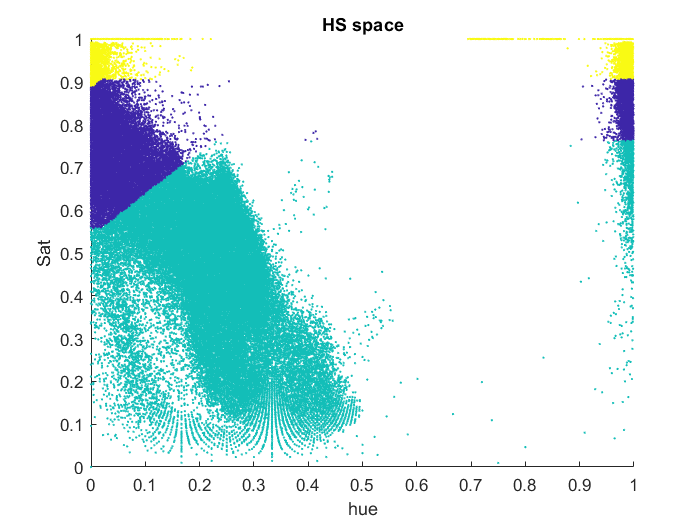

%Algo no va. Els pebrots vermells queden mal segmentats. (COMTE! EL RESULTAT DE
%KMEANS ÉS SEMPRE DIFERENT. DEPÈN DE L%EXECUCIÓ, EL RESULTAT PODRIA
%SORTIT MILLOR O PITJOR)
%Què està passant ?
% Representem els píxels en l’espai hue-sat
figure,scatter(vect(:,1),vect(:,2),1,cluster_idx);
xlabel('hue');ylabel('Sat')
title('HS space')

% El hue és un angle. És cíclic.
% Píxels vermells amb hue molt similars queden a banda i banda de l’espai hue-sat per culpa del
%pas per zero.

## Exercici

%la funció kmeans implementada a matlab no funciona amb aritmètica cíclica, per tant, les
%característiques no poden ser angles.
%Implementeu vosaltres una funció kmeans que pugui treballar amb característiques cícliques.